% close(1);

R = 0.01% Pinion gear effective radius

R = 0.0100

J = 2.76e-6 + 1.72e-7% Motor and pinion moment of inertia

J = 2.9320e-06

m = 4*.343% Mass of rack and plunger

m = 1.3720

b = 0% Rotational damping coefficient (includes back emf)

b = 0

c = 286.8% Linear damping coefficient (includes friction and damping from chest compressions)

c = 286.8000

k = 10490% Spring constant of chest

k = 10490


T = 1e-3; % Sampling rate of slowest sensor

s = tf('s');

tau_FOC = 0.00016

tau_FOC = 1.6000e-04


% Full plant, used to size controller gain
plant = (1/(tau_FOC*s + 1))*(R/((J + m*R^2)*s^2 + (b + c*R)*s + k*R^2));
[plant_num, plant_denom] = tfdata(plant);
plant_num = plant_num{1};
plant_denom = plant_denom{1};

w_c = 2*pi*20 % rad/s

w_c = 125.6637

phi_m = 45 % deg

phi_m = 45

phi_lag = rad2deg(angle(freqresp(plant, w_c))) - 45 % deg

phi_lag = -136.3369


K_i = w_c/tand(90 - phi_lag)

K_i = 119.9322

alpha = (1 + sind(phi_m + phi_lag))/(1 - sind(phi_m + phi_lag))

alpha = 1.3612e-04

tau = 1/(w_c*sqrt(alpha))

tau = 0.6821


lead_tf = (alpha*tau*s + 1)/(tau*s + 1);
lag_tf = 1 + K_i/s;

K_p = 1/abs(freqresp(plant*lag_tf, w_c))

K_p = 2.6077e+04


controller_tf = K_p*lag_tf;
L = controller_tf*plant;

[num_cont, denom_cont] = tfdata(lag_tf); 
% Generate discrete TF

% lead_discrete = c2d(lead_tf, T, 'matched');
lag_discrete = c2d(lag_tf, T, 'Tustin');
leadlag_discrete = lag_discrete;
gain_discrete = abs(freqresp(K_p*lag_tf, .001))/abs(freqresp(leadlag_discrete, .001));

discrete_tf = leadlag_discrete*gain_discrete


discrete_tf =
 
  2.764e04 z - 2.451e04
  ---------------------
          z - 1
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


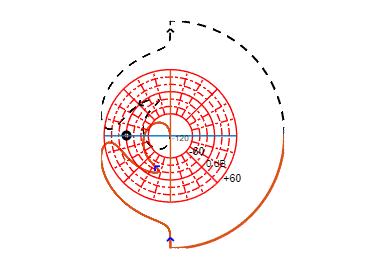

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


[num_discrete, denom_discrete] = tfdata(discrete_tf);
num_discrete = num_discrete{1};
denom_discrete = denom_discrete{1};

figure(1);
nyqlog(L)

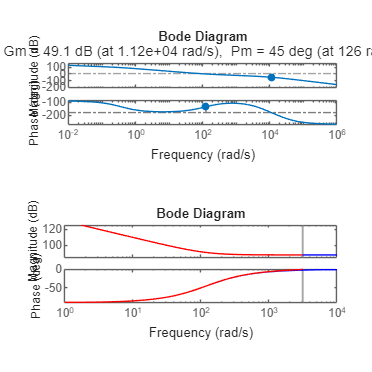


figure(2);
subplot(2, 1, 1)
margin(L)
subplot(2, 1, 2)
bode(controller_tf, 'b')
hold on;
bode(discrete_tf, 'r')
improvePlot


% Verify Sensitivity constraint, S < 2
Sens_max = getPeakGain(1/(1 + L))

Sens_max = 1.3125

disp(Sens_max < 2)

   1

